# Übung 6

## 6.1 Startup

Stellen Sie durch zwei geeignete Matlab-Befehle sicher, dass

- der Workspace initialisiert ist,

- alle Figures (Diagrammfenster) geschlossen sind und

- die Darstellung der Ergebnisse 'compact', also ohne zusätzliche Leerzeilen erfolgt.

close all
clear all
clc
format compact

Im Folgenden ergänzen/erweitern Sie dieses Script. Sofern nicht anders angegeben, unterdrücken Sie die Ergebnisausgabe (Strichpunkt am Zeilenende). Wenn Sie alle Übungsaufgaben bearbeitet haben, publizieren ('publishen') Sie das Skript als PDF. Geben Sie dieses PDF (und nur dieses PDF) zur Kontrolle ab (moodle/Laufwerk/email).

## 6.2 Messdaten

Bei einem Experiment mit einem optischen Prisma wurden mit einem Goniometer (Winkelmesser) für verschiedene Wellenlängen unterschiedliche Brechungswinkel ermittelt. Diesen Effekt bezeichnet man als Dispersion. Sind die Dispersionseigenschaften des Prismas bekannt, so kann man aus gemessenen Brechungswinkeln Wellenlängen bestimmen.

% Bei folgenden (exakt angenommenen) Wellenlängen 
% wurde gemessen 
lambda = [ 
%   nm            Farbe
    707;        % rot1
    668;        % rot2
    588;        % gelb
    505;        % türkis1
    502;        % türkis2
    492;        % türkis3
    471;        % blau1
    447;        % blau2
    439         % violett1
]

lambda =    707
   668
   588
   505
   502
   492
   471
   447
   439


Licht der o.g. Wellenlängen wurde durch das Prisma wie folgt gebrochen:

phi_dms = [ 
%   Grad Minuten Sekunden
% Grad, Minuten, Sekunden (dms = degrees, minutes, seconds)
    47 19 0;   % rot1, 47° 19' 0'', 47 Grad, 19 Minuten, 0 Sekunden
    47 29 0;   % rot2
    48  5 0;   % gelb
    48 58 0;   % türkis1
    49  0 0;   % türkis2
    49  8 0;   % türkis3
    49 30 0;   % blau1
    49 59 0;   % blau2
    50 12 0    % viloett1
];

Alle Werte seien auf +- 1' genau bestimmt.

## 6.3 Umrechnung in Grad und Plot

Um mit den Brechungswinkeln rechnen zu können ist zunächst eine Umrechnung in Dezimalgrad nötig. Erstellen Sie eine Funktion *dms2deg* (degrees, minutes, seconds to degrees) und benutzen Sie diese, um den ganzen Vektor *phi_dms* auf ein Mal in einen Dezimalgrad-Vektor umzurechnen.

Hinweis: Eine Minute ist (1/60) Grad, eine Sekunde ist (1/60) Minute.

Verwenden Sie also weder beim Funktionsaufruf, noch in der Funktion selbst Schleifen!

Zur Anzeige der Datei *dms2deg.m* an diese Stelle verwenden Sie den Befehl "type dms2deg.m"

type dms2deg.m

function phi_deg = dms2deg( phi_dms )
%UNTITLED Summary of this function goes here
% Detailed explanation goes here
phi_deg = phi_dms(:,1) + phi_dms(:,2)/60;
end



% function result = dms2deg(dms)
% 
%     % https://www.rapidtables.com/convert/number/degrees-minutes-seconds-to-degrees.html
%     deg = dms(:, 1);
%     min = dms(:, 2);
%     sec = dms(:, 3);
% 
%     result = deg + min .* 1/60 + sec .* 1/3600;
% 
% end


degrees_decimal = dms2deg(phi_dms)

degrees_decimal =    47.3167
   47.4833
   48.0833
   48.9667
   49.0000
   49.1333
   49.5000
   49.9833
   50.2000


Zeigen Sie in einem Diagramm die Wellenlängen über den berechneten Winkeln an, also *lambda*(*phi*).

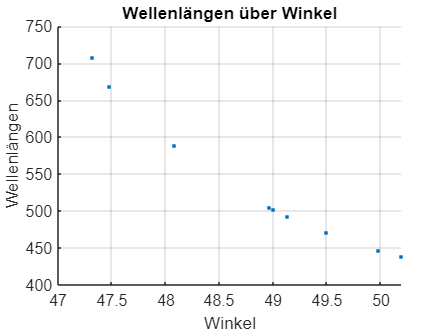

figure
newplot()

hold on

% myPlot is defined at the very bottom of this script
myPlot(degrees_decimal, lambda, 'Wellenlängen über Winkel', 'Winkel', 'Wellenlängen')

hold off

## 6.4 Mittlere Brechung und Brechungsindex

Berechnen Sie den mittleren Brechungswinkel und, für diesen Winkel, den Brechungsindex *n2* des verwendeten Materials. Das verwendete Prisma ist ein gleichseitiges, d.h. der brechende Winkel Epsilon beträgt 60°.


$$ n_2 = \frac{sin((\phi+\epsilon)/2)}{sin(\epsilon/2)} $$


Hinweis: O.g. Gleichung gilt nur, wenn das Prisma so justiert wurde, dass die Brechnung minimal ist. Dann ist der Winkel des in das Prisma einfallenden Strahls gleich dem Winkel des austretenden Stahls. Gehen Sie davon aus, dass diese Bedingung erfüllt ist.

phi_m = mean(degrees_decimal)

phi_m = 48.8519

epsilon = 60

epsilon = 60


n2 = sin((phi_m + epsilon)/180*pi/2) / (sin(epsilon/180*pi/2))

n2 = 1.6267

Welche Glasarten finden Sie, wenn Sie diesen Brechungsindex recherchieren?

% Glasarten: Flintglas

## 6.5 Polynomfitting (2. Grades)

Damit sind die Brecheigenschaften des verwendeten Glases bekannt. Nun geht es um die Charakterisierung der Wellenlängenabhängigkeit dieses Brechungswinkels, der Dispersion. Diese kann mit einer Kurve charakterisiert werden. Benutzen Sie die Funktion *polyfit* um ein Polynom zweiten Grades zu finden, das die gegebenen Punkte ( *lambda*(*phi*) ) interpoliert. Speichern Sie auch die Strukur *S* (*help polyfit*) mit ab, Sie brauchen diese später für die Fehlerrechnung.

% p = polyfit(x, y, n)
% fits polynomial of degree n that is a best fit 
% (in a least-squares sense) for the data in y
% 
% Return values:
% p is the polynomial
% s is a struct describing???
[p s] = polyfit(degrees_decimal, lambda, 2);

Geben Sie den Koeffizientenvektor aus.

p

p = 1.0e+04 *

    0.0024   -0.2393    6.1035


N = length(p)

N = 3

%p(1)

s

s = struct with fields:
        R: [3×3 double]
       df: 6
    normr: 11.3846

s.R

ans = 1.0e+03 *

   -7.1679   -0.1466   -0.0030
         0   -0.0029   -0.0001
         0         0    0.0000


## 5.6 Funktion polyout

Schreiben Sie nun eine Funktion *polyout( fun, var, p )* , die das durch *p* beschriebene Polynom wie folgt ausgibt:

%>>polyout( 'y', 'x', p );
% y(x)=
%  <p(1)> x^(N-1) +
%  <p(2)> x^(N-2) +
%  ... +
%  <p(N)>

Hinweis: *polyout* sollte mit Polynomen beliebiger Ordnung zurecht kommen. Der Grad des Polynoms kann der Länge von *p* entnommen werden.

Zur Anzeige der Datei polyout*.m* an diese Stelle verwenden Sie den Befehl "type polyout.m"

type polyout.m

function polyout( fun, var, p )
%polyout( fun, var, p ) Gibt ein polynom p in menschenlesbarer Schreibweise aus
% Parameter fun is the name of the function as passed in by the caller
% Parameter var is the name of the variable to fun as passed in by the caller
% Parameter p is the polynomial as returned by the polyfit function for
% example
% Das Ausgabeformat ist:
% fun(var)=
% <p(1)> var^(N-1) +
% <p(2)> var^(N-2) +
% ... +
% <p(N)>
 N = length(p);
 fprintf('%s(%s)= \n', fun, var);
for i = 1:N-1
 fprintf(' %f %s^%d + \n', p(i), var, N-i);
end
 fprintf(' %f\n', p(end));
end


polyout('y', 'x', p);

y(x)= 
 23.615823 x^2 + 
 -2392.554465 x^1 + 
 61034.738355


## 6.7 Fitting testen

Nun kennen Sie die Polynomkoeffizienten, aber passt das gefundene Polynom auch zu den gemessenen Werten? Zeichnen Sie das Polynom in das Diagramm mit den Messpunkten ein. Natürlich brauchen Sie mehr Punkte, um die Kurve schön darstellen zu können. Benutzen Sie einfach *linspace*, um viele Punkte zwischen dem kleinsten und dem größten Brechungswinkel zu erzeugen.

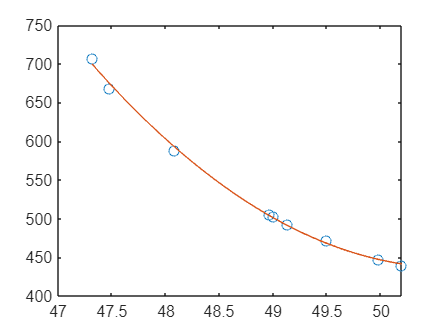

% points using linspace
%x1 = linspace(0, 4*pi);
x1 = linspace(min(degrees_decimal), max(degrees_decimal));
y1 = polyval(p, x1);

% only points for degrees_decimal
%y1 = polyval(p, degrees_decimal);

figure
plot(degrees_decimal, lambda, 'o')
hold on
plot(x1, y1)
hold off

Benutzen Sie dann die Funktion *polyval* um die Funktionswerte zu berechnen.

...

Plotten Sie die Funktionswerte jetzt in das Diagramm, das schon die Messpunkte enthält (keine neue figure, *hold on*). Beschriften Sie das Diagramm und erzeugen Sie eine Legende.

...

## 6.8 Charakterisierung von LEDs

In einem zweiten Experiment wird Licht verschiedener LEDs durch das Prisma gebrochen. Dabei entsteht kein Spektrum mit diskreten Wellenlängen (wie vorher), sondern ein Kontinuum (also eine Art ´Regenbogen´). Es wurden für das Licht jeder LED der minimale und der maximale Brechnungswinkel bestimmt.

Berechnen Sie für *eine* der folgenden LEDs aus den Brechungswinkeln die minimale und maximale Wellenlänge mít Fehler. Der Fehler besteht aus einem Fehler aus der Kurvenanpassung und der Fehlerfortpflanzung des Ablesefehlers durch das Polynom!

Den Fehler der Kurvenanpassung finden Sie im Parameter *delta* der Funktion *polyval*, die dies aber nur berechnen kann, wenn Sie den Parameter *S* der Kurvenanpassung (*polyfit*) mit übergeben.

Um herauszufinden, wie stark sich ein Ablesefehler von z.B. +- 1' auf die Wellenlänge auswirkt, müssen Sie die Fittingfunktion ableiten (*polyder*) um die Steigung an der Stelle *phi* zu berechnen. Mit dieser Steigung wirkt sich ein Winkelfehler auf die Wellenlänge aus:


$$ _\Delta\lambda = |\frac{\delta\lambda}{\delta\phi}|_{\phi} \cdot _\Delta\phi $$


Benutzen Sie auch hier die Funktion *polyout* um sich das Ergebnis der Ableitung anzeigen zu lassen.

Geben Sie alle berechneten Wert einzeln an: Mittelwert, Fehler durch Kurvenanpassung, fortgepflanzter Ablesefehler. Fassen Sie dann die Ergebnisse zusammen.

Überprüfen Sie, anhand des Diagrammes aus Aufgabe 4.6, mit Lineal oder Geodreieck ob die berechneten Wellenlängen plausibel sind.

## Auswertung LED

Messdaten

phi_dms = [ 47 36 0; 47 57 0; ];    % LED R-630
% phi_dms = [ 47 41 0; 48 15 0; ];  % LED O-610
% phi_dms = [ 47 54 0; 48 24 0; ];  % LED YH-590LED YG-574
% phi_dms = [ 47 58 0; 48 35 0; ];  % LED YG-574
% phi_dms = [ 47 51 0; 49 0 0; ];   % LED G-525
% phi_dms = [ 47 55 0; 49 20 0; ];  % LED BG-505
% phi_dms = [ 47 35 0; 49 50 0; ];  % LED B-470

Umrechnung in Dezimalgrad

% Dezimalgrad
phi = dms2deg(phi_dms);

Wellenlänge und Fittingfehler bestimmen

% Wellenlänge und Fittingfehler bestimmen
% dlda1 speichert den Fittingfehler
[ lda dlda1 ] = polyval(p, phi, s);

Fortpflanzung Ablesefehler

% Ableiten der Fittingfunktion
dp = polyder(p);

% Anzeigen der Fittingfunkton
polyout('dlambda/dphi', '', dp);

dlambda/dphi()= 
 47.231647 ^1 + 
 -2392.554465



% Berechnen der Fehlerfortpflanzung für 1/60°
dlda2 = abs(polyval(dp, phi)) * 1/60;

Berechnen der Fehlerfortpflanzung für 1/60°

% Einzelausgabe
fprintf( 'Auswertung für LED R-630:' );

Auswertung für LED R-630:

fprintf( 'Mittelwert +- (Fittingfehler + Fehlerfortpflanzung)\n' );

Mittelwert +- (Fittingfehler + Fehlerfortpflanzung)


fprintf( 'lambda_min= (%f +- (%f + %f))nm\n', lda(1), dlda1(1), dlda2(1) );

lambda_min= (656.933579 +- (5.316760 + 2.405468))nm


fprintf( 'lambda_max= (%f +- (%f + %f))nm\n\n', lda(2), dlda1(2), dlda2(2) );

lambda_max= (609.311686 +- (5.160001 + 2.129950))nm




% Summe der Fehler
dlda = dlda1 + dlda2;

% Zusammenfassung
%FormOut( 'phi_min', phi(1), 1/60, '°' );
%FormOut( 'phi_max', phi(2), 1/60, '°' );
%FormOut( 'lamda_max', lda(1), dlda(1), 'nm' );
%FormOut( 'lamda_min', lda(2), dlda(2), 'nm' );

% LED O-610: phi_dms = [ 47 41 0; 48 15 0; ];
% LED YH-590: phi_dms = [ 47 54 0; 48 24 0; ];
% LED YG-574: phi_dms = [ 47 58 0; 48 35 0; ];
% LED G-525: phi_dms = [ 47 51 0; 49 0 0; ];
% LED BG-505: phi_dms = [ 47 55 0; 49 20 0; ];
% LED B-470: phi_dms = [ 47 35 0; 49 50 0; ];